# Data Fitting

We wish to compute the value of a resistance. To do so, we take a current generator and measure the voltage over the resistance, knowing that


$$V=\textrm{RI}\ldotp$$


We now generate a vector of input currents $I$ and a vector of output voltages $V$ which, unfortunately, are currupted by a Gaussian noise

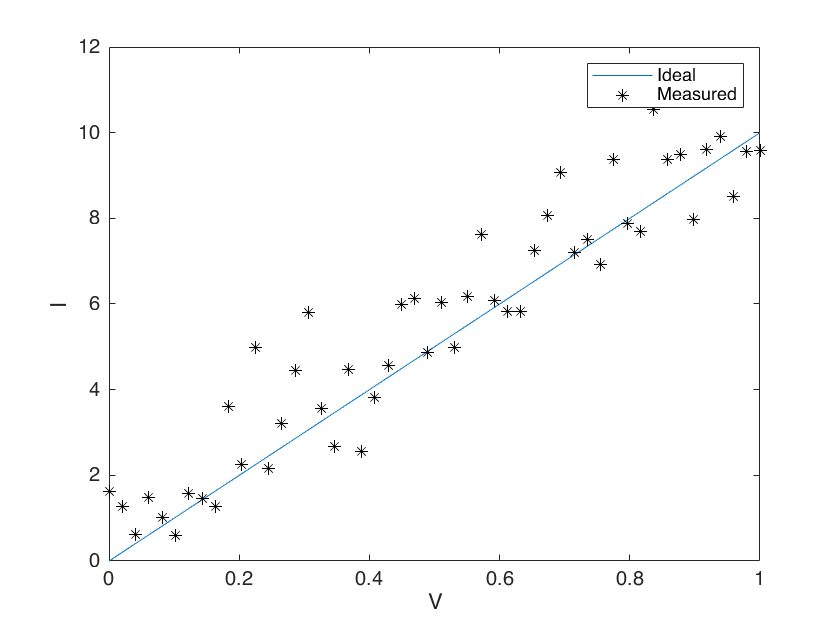

close all

% True Value of the Resistance
R = 10;

% Input Currents
I = linspace(0,1,50);

% Output Voltage (Ideal)
V0 = R*I;

% Output Voltage (Noisy)
V = V0 + randn(size(V0));

plot(I,V0,I,V,'*k')
xlabel('V')
ylabel('I')
legend('Ideal','Measured')

To estimate the value of R, we use the function **polyfit** to fit our data with a 1st order polynomial. Ideally, the solution should be P = [10 0]. We'll get something close, but not exact. 

P = polyfit(I,V,1)

P =     9.4093    0.7770


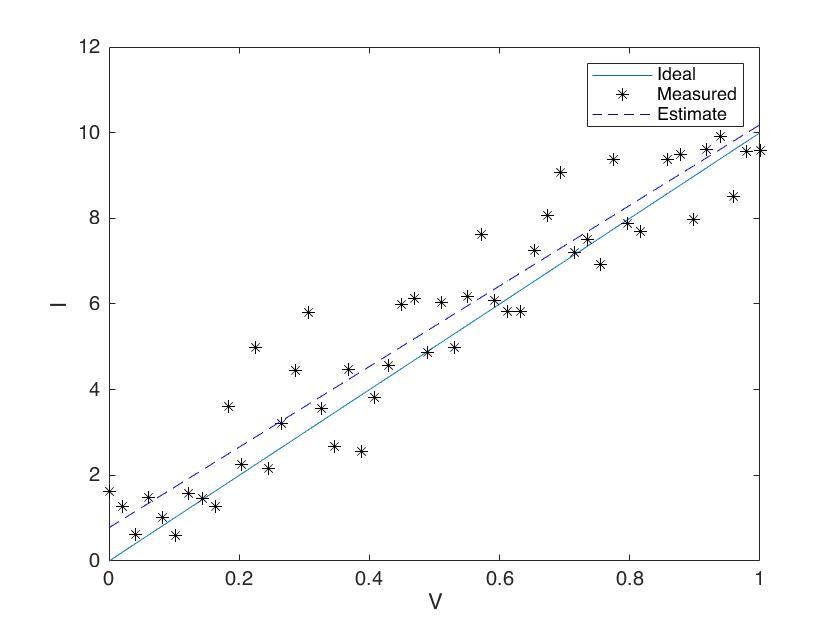


V1 = P(1)*I+P(2);
 
plot(I,V0,...
     I,V,'*k', ...
     I,V1,'--b')
xlabel('V')
ylabel('I')
legend('Ideal','Measured','Estimate')

To improve the fit, one could be temped to increase the order of the polynomial. However, this is a **bad idea**:

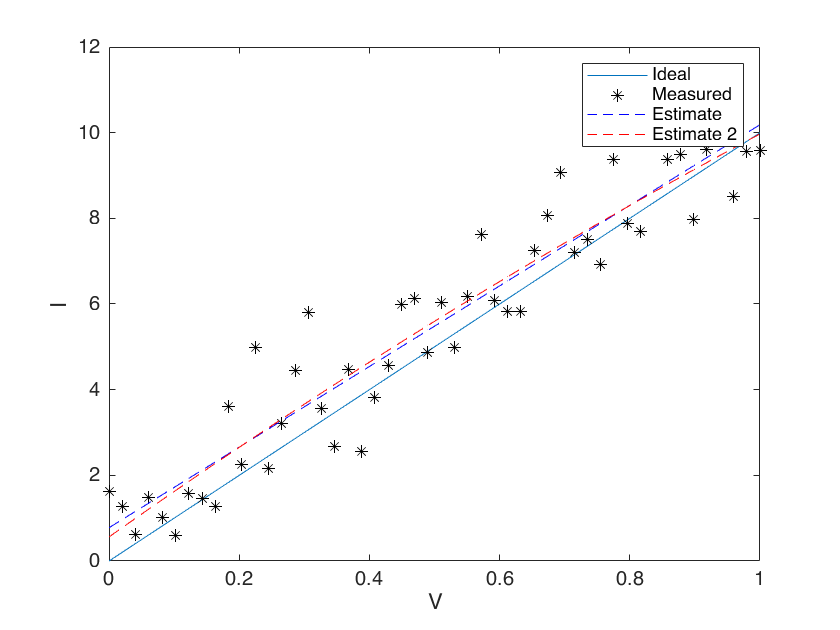

P2 = polyfit(I,V,2);

V2 = P2(1)*I.^2+P2(2)*I+P2(3);

plot(I,V0,...
     I,V,'*k', ...
     I,V1,'--b', ...
     I,V2,'--r')
xlabel('V')
ylabel('I')
legend('Ideal','Measured','Estimate','Estimate 2')

The reason why using a second order polynomial is a bad idea is not obvious if we stay in the range of currents for which we made our measurements, but it becomes painfully clear when we try to extrapolate the behavior for higher values of $I$.

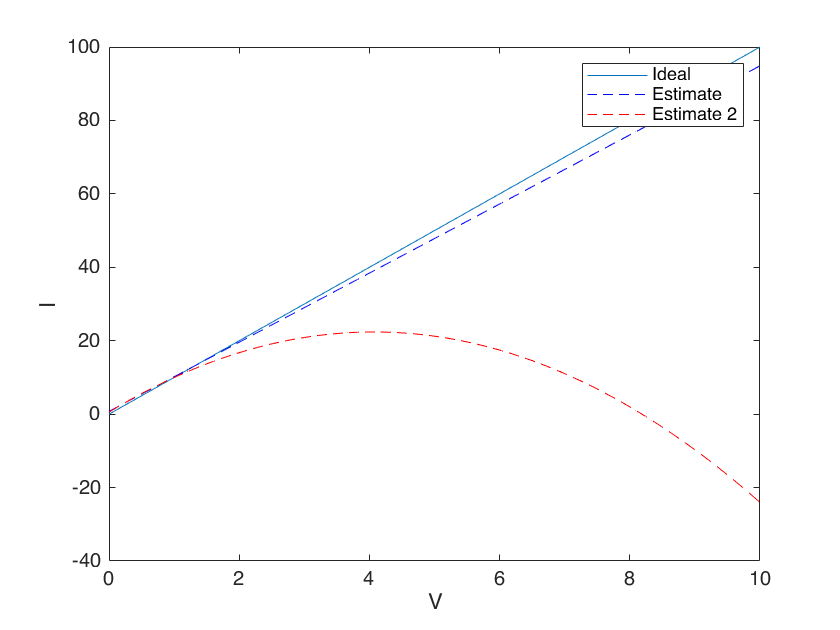

% Input Currents
I = linspace(0,10,200);

V0 = R*I;
V1 = P(1)*I+P(2);
V2 = P2(1)*I.^2+P2(2)*I+P2(3);

plot(I,V0,...
     I,V1,'--b', ...
     I,V2,'--r')
xlabel('V')
ylabel('I')
legend('Ideal','Estimate','Estimate 2')

The moral of the story: **Don't overfit your data!**

Fitting data with a lower order polynomial is typically the better choice. Only use high order polynomials if you can justify why a lower order polynomial is not good enough. 

# Fitting Exponentials

Unfortunately, not every natural phenomena is polynomial, even though that is the easiest thing we know how to fit. Fortunately, just because something is not polynomial doesn't mean we can't turn it into one!

Consider the case


$$y={a\;e}^{\mathrm{bx}}$$


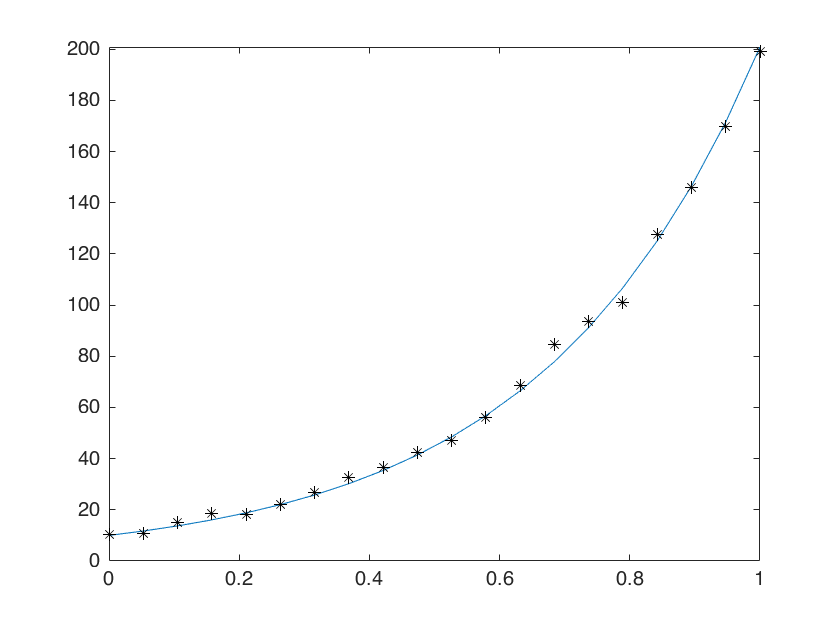

a = 10;
b = 3;

x = linspace(0,1,20);

% Ideal Curve
y0 = a*exp(b*x);

% Measurements (note that the noise is also exponential)
y = y0 + randn(size(y0)).*exp(2*x);

plot(x,y0,x,y,'*k')

Although it's not linear, if we define $z=\mathrm{log}\left(y\right)$ we get


$$z=\mathrm{log}\left(a\right)+\mathrm{bx},$$


Which is a nice, first order polynomial that we know how to fit

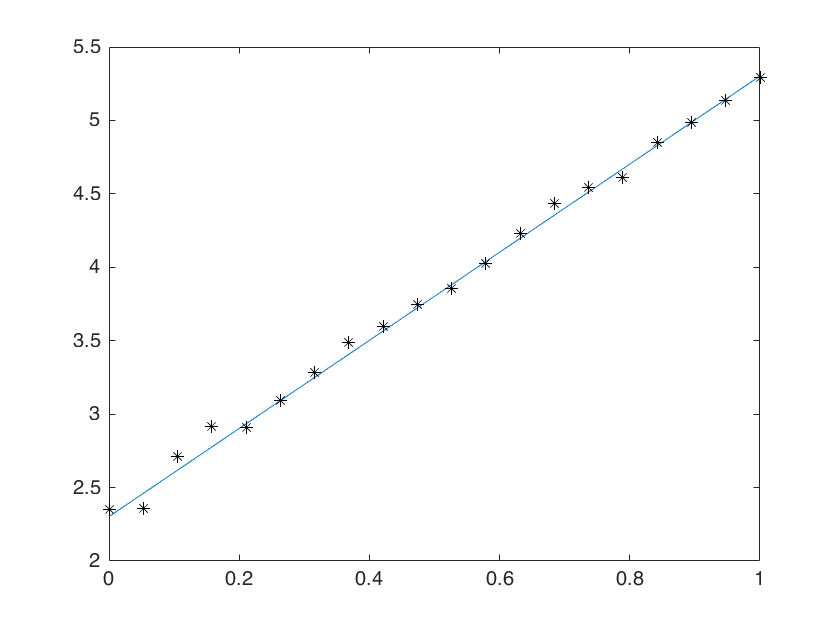

% Redo everything using log(y)
z0 = log(y0);
z = log(y);

plot(x,z0,x,z,'*k')


% Linear fit
P = polyfit(x,z,1)

P =     2.9591    2.3418



% Recover the exponential
y1 = exp(P(1)*x+P(2))

y1 =    10.3995   12.1521   14.2000   16.5930   19.3893   22.6569   26.4752   30.9369   36.1505   42.2428   49.3617   57.6804   67.4009   78.7596   92.0326  107.5423  125.6658  146.8436  171.5903  200.5075


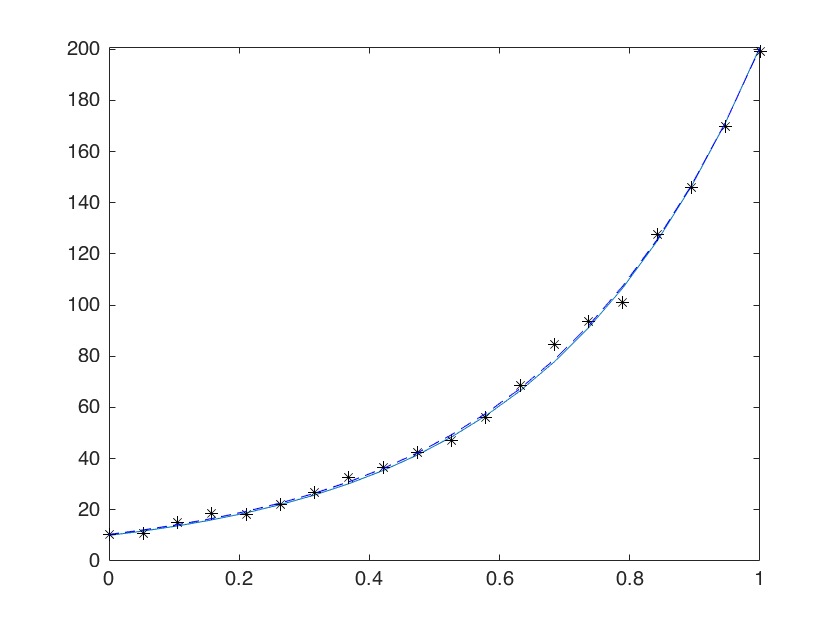


% Check fit quality
plot(x,y0,x,y,'*k',x,y1,'--b')